%% build_SummaryTable.m
% Scan a folder of per-cell Excel files, extract metadata from filenames,
% read 1–3 rows based on condition keys, map values by header name,
% and write a single SummaryTable.xlsx to the same folder.

% ---------- User input ----------
inputFolder = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/output_test';
% --------------------------------

% Output schema (exact order)
outVars = { ...
    'CellID','treatment','wpi','condition_filename','date','cellNumber', ...
    'Expter_Name', ...                                %%% <<< CHANGED (added column)
    'Expt_cond', ...
    'I_0_3','I_1','I_3','I_10','I_30','I_100','I_300','I_1000', ...
    'avgRundown_per_iteration','threshold','Rmax','pchipSlope' ...
};

outTypes = [ ...
    repmat({'string'},1,8), ...                      %%% <<< CHANGED (was 7 text cols; now 8 incl. Expter_Name)
    repmat({'double'},1,12) ...
];

% Prepare empty summary table with fixed schema
SummaryTable = table('Size',[0 numel(outVars)], ...
    'VariableTypes',outTypes,'VariableNames',outVars);

% Gather files (.xlsx and .xls)
files = [dir(fullfile(inputFolder,'*.xlsx')); dir(fullfile(inputFolder,'*.xls'))];
files = files(~[files.isdir]);  % safety

if isempty(files)
    fprintf('No .xlsx or .xls files found in: %s\n', inputFolder);
end

for k = 1:numel(files)
    fpath = fullfile(files(k).folder, files(k).name);
    [~, base, ~] = fileparts(fpath);

    % ---- Parse filename (split by underscores only) ----
    % Expected patterns (condition may include underscores/hyphens):
    % 1) treatment _ wpi _ condition _ date _ cellToken
    % 2) treatment _ wpi _ condition _ date _ cellToken _ Expter
    try
        meta = parseFilenameTokens(base); % no regexp for tokenization
    catch ME
        warning('Skipping file (bad filename format): %s\n  -> %s', files(k).name, ME.message);
        continue;
    end

    % Determine search keys (ordered aCSF -> GBZ -> NBQX_APV)
    keys = computeKeys(meta.condition_filename);

    fprintf('Processing: %s\n', files(k).name);

    % Try to read the first sheet
    T = [];
    try
        T = readtable(fpath, 'FileType','spreadsheet');
    catch ME
        warning('  Could not read file: %s\n  -> %s', files(k).name, ME.message);
        continue;
    end

    % Normalize header names for mapping (case/space-insensitive)
    varNames = string(T.Properties.VariableNames);
    normMap = buildHeaderIndex(varNames);  % containers.Map of normalizedName -> colIndex

    % Column A (first column) will be used for matching search keys
    colA = string(strtrim(T{:,1}));
    colA_lower = lower(colA);

    % For each key, append matches (all rows) or a single NaN row if none
    for qi = 1:numel(keys)
        key = keys(qi);
        mask = strcmp(colA_lower, lower(strtrim(key)));
        idx = find(mask);

        if isempty(idx)
            fprintf('  Key %-9s : NO match -> append NaNs\n', key);
            SummaryTable = [SummaryTable; buildOutRow(meta, key, T, [], normMap)]; %#ok<AGROW>
        else
            fprintf('  Key %-9s : %d match(es)\n', key, numel(idx));
            for ii = 1:numel(idx)
                SummaryTable = [SummaryTable; buildOutRow(meta, key, T, idx(ii), normMap)]; %#ok<AGROW>
            end
        end
    end
end

Processing: MMZ_2w_aCSF-GBZ-NBQX_APV_250101_cell2_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)
  Key NBQX_APV  : 1 match(es)


Processing: MMZ_2w_aCSF-GBZ-NBQX_APV_250827_cell7_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)
  Key NBQX_APV  : 1 match(es)


Processing: PBS_2w_aCSF-GBZ-NBQX_APV_250201_cell3_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)
  Key NBQX_APV  : 1 match(es)


Processing: PBS_2w_aCSF-GBZ-NBQX_APV_250827_cell7_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)
  Key NBQX_APV  : 1 match(es)



% Write output
outFile = fullfile(inputFolder, 'SummaryTable.xlsx');
writetable(SummaryTable, outFile);
fprintf('Done. Wrote %d rows to %s\n', height(SummaryTable), outFile);

Done. Wrote 12 rows to /Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/output_test/SummaryTable.xlsx




%% ----------------- Helper functions -----------------

function meta = parseFilenameTokens(base)
% Parse tokens from basename (no path/extension).
% Tokenization policy: split on '_' only.
% Supports two endings:
%   ... _ date _ cellN
%   ... _ date _ cellN _ Expter
    parts = split(string(base), '_');
    if numel(parts) < 5
        error('Expected at least 5 underscore-separated tokens.');
    end

    treatment = parts(1);
    wpi       = parts(2);

    %%% <<< CHANGED: allow optional trailing experimenter token
    % Detect whether the last token is a cell token or an experimenter.
    lastTok = parts(end);
    if startsWith(lower(lastTok), "cell") || ~isempty(regexp(lastTok, '^cell\d+$', 'once'))
        % No experimenter in filename
        expter    = "";                          % none
        cellToken = parts(end);
        dateStr   = parts(end-1);
        if numel(parts) == 5
            condition = parts(3);
        else
            condition = strjoin(parts(3:end-2), '_');
        end
    else
        % Has experimenter (e.g., ... _ cell2 _ HM)
        expter    = lastTok;
        cellToken = parts(end-1);
        dateStr   = parts(end-2);
        if numel(parts) == 6
            condition = parts(3);
        else
            condition = strjoin(parts(3:end-3), '_');
        end
    end
    %%% <<< end CHANGED

    % Extract numeric cell number from cellToken (e.g., "cell7" -> 7). If missing -> NaN.
    tok = regexp(cellToken, '\d+', 'match', 'once');  % allowed here (not for tokenization)
    if isempty(tok), cellNum = NaN; else, cellNum = str2double(tok); end

    % Preserve originals as strings (except numeric cellNumber)
    meta = struct();
    meta.CellID             = string(base);
    meta.treatment          = treatment;
    meta.wpi                = wpi;
    meta.condition_filename = condition;
    meta.date               = dateStr;
    meta.cellNumber         = cellNum;
    meta.Expter_Name        = string(expter);         %%% <<< CHANGED (store experimenter)
end

function keys = computeKeys(condition_filename)
% Build ordered list of keys based on condition in filename.
    c = lower(condition_filename);
    keys = string({'aCSF'});  % always
    if contains(c, 'gbz')
        keys(end+1) = "GBZ";
    end
    if contains(c, 'nbqx_apv')
        keys(end+1) = "NBQX_APV";
    end
end

function norm = normName(s)
% Normalize header names for robust matching (case- and space-insensitive).
    norm = lower(regexprep(strtrim(string(s)), '[^\w]|[ ]', ''));
end

function normMap = buildHeaderIndex(varNames)
% Build lookup of normalized variable names -> column index
    normMap = containers.Map('KeyType','char','ValueType','double');
    for i = 1:numel(varNames)
        key = char(normName(varNames(i)));
        if ~isKey(normMap, key)
            normMap(key) = i;
        end
    end
end

function rowT = buildOutRow(meta, key, T, rowIdx, normMap)
% Construct a one-row table in the required schema, pulling values by header name.
    outVars = { ...
        'CellID','treatment','wpi','condition_filename','date','cellNumber', ...
        'Expter_Name', ...                            %%% <<< CHANGED (added column)
        'Expt_cond', ...
        'I_0_3','I_1','I_3','I_10','I_30','I_100','I_300','I_1000', ...
        'avgRundown_per_iteration','threshold','Rmax','pchipSlope' ...
    };
    outTypes = [ ...
        repmat({'string'},1,8), ...                  %%% <<< CHANGED (text count updated)
        repmat({'double'},1,12) ...
    ];

    % Initialize with empties/NaNs
    rowT = table('Size',[1 numel(outVars)], ...
        'VariableTypes',outTypes,'VariableNames',outVars);

    % Fill metadata/text fields
    rowT.CellID             = meta.CellID;
    rowT.treatment          = meta.treatment;
    rowT.wpi                = meta.wpi;
    rowT.condition_filename = meta.condition_filename;
    rowT.date               = meta.date;
    rowT.cellNumber         = meta.cellNumber;
    rowT.Expter_Name        = meta.Expter_Name;      %%% <<< CHANGED (populate new column)
    rowT.Expt_cond          = string(key);

    % If no matching data row, leave numeric as NaN
    if isempty(rowIdx)
        return;
    end

    % Map source headers -> target names (one-to-one by name)
    targetNames = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000", ...
                   "avgRundown_per_iteration","threshold","Rmax","pchipSlope"];

    for t = 1:numel(targetNames)
        tgt = targetNames(t);
        srcKey = char(normName(tgt));
        if isKey(normMap, srcKey)
            col = normMap(srcKey);
            val = T{rowIdx, col};
            rowT.(tgt) = coerceDouble(val);
        else
            rowT.(tgt) = NaN;
        end
    end
end

function x = coerceDouble(val)
% Coerce a scalar/1x1 cell/char/string to double; non-numeric -> NaN.
    if iscell(val), val = val{1}; end
    if isnumeric(val) && isscalar(val)
        x = double(val); return;
    end
    if isstring(val) || ischar(val)
        tmp = str2double(strtrim(string(val)));
        x = tmp; if isnan(tmp), x = NaN; end
        return;
    end
    try
        x = double(val);
        if ~isscalar(x), x = NaN; end
    catch
        x = NaN;
    end
end

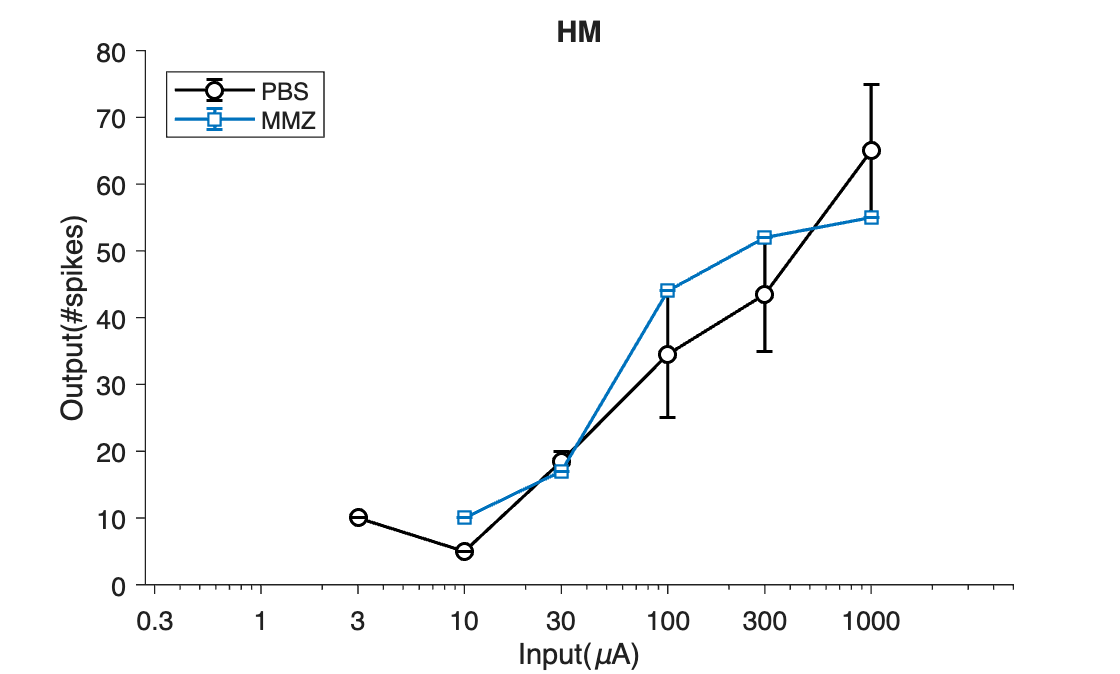

% === HM 2w_MMZ_aCSF vs HM 2w_PBS_aCSF ===

fname = 'SummaryTable.xlsx';   % adjust path if needed
T = readtable(fname, 'FileType','spreadsheet');

% --- Set up filters for grouping comparisons ----

% list out columns names needed for grouping
needCols = {'Expter_Name','wpi','Expt_cond'};

% normalise column content into strings
for k = 1:numel(needCols)
    % check for matching columns, throws an error if missing
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    
    % convert column content from char to string and remove tailing spaces
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

% Filter: HM, 2w, aCSF
mask = strcmpi(T.Expter_Name, "HM") & ...
       strcmpi(T.wpi,         "2w") & ...
       strcmpi(T.Expt_cond,   "aCSF");

T_HM_2w_aCSF = T(mask,:);

% --- (1) check repeated CellID ---
ids = string(T_HM_2w_aCSF.CellID);
[u, ~, ic] = unique(ids,'stable');
counts = accumarray(ic,1);
dups = u(counts>1);
if ~isempty(dups)
    error('repeated cell: %s', strjoin(cellstr(dups), ', '));
end

% % --- (2) Cell count per treatment ---
T2 = T_HM_2w_aCSF;
T2.treatment = string(T2.treatment);
% CellCountTbl = groupcounts(string(T2.treatment));
% CellCountTbl.Properties.VariableNames = {'treatment','CellCount'};

% --- (3) column means / SD / SEM per treatment ---
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","pchipSlope"];
varsAll    = [varsSpikes varsParams];

% converting datatype into double
for v = varsAll
    x = T2.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end

    % Make sure it is a Nx1 vector, with N beling all values in x
    T2.(v) = reshape(x,[],1);
end

% Per treatment, calculate mean, SEM & SD for IO, threshold, Rmax & slope 
treats = unique(T2.treatment,'stable');
stats = struct();

% Looping through each treatment...
for i = 1:numel(treats)
    
    % Builds a logical mask selecting the rows in T2 
    % that belong to current treatment - treats(i)
    tr = treats(i);
    rows = (T2.treatment==tr);

    % indexing IO columns for current treatment
    Xspk = T2{rows, varsSpikes};
    % Column-wise calculation
    mSpk = mean(Xspk, 1, 'omitnan');
    sdSpk = std(Xspk, 0, 1, 'omitnan');
    nSpk  = sum(~isnan(Xspk), 1);
    semSpk = sdSpk ./ max(nSpk,1).^0.5;

    % indexing parameter columns...
    Xpar = T2{rows, varsParams};
    mPar = mean(Xpar, 1, 'omitnan');
    sdPar = std(Xpar, 0, 1, 'omitnan');
    nPar  = sum(~isnan(Xpar), 1);
    semPar = sdPar ./ max(nPar,1).^0.5;

    stats.(tr).meanSpikes = mSpk;
    stats.(tr).sdSpikes   = sdSpk;
    stats.(tr).semSpikes  = semSpk;
    stats.(tr).nSpikes    = nSpk;
    stats.(tr).meanPars   = mPar;
    stats.(tr).sdPars     = sdPar;
    stats.(tr).semPars    = semPar;
    stats.(tr).nPars      = nPar;
end

% --- (4) overlay line plot: mean ± SEM across intensities ---
xVals = [0.3 1 3 10 30 100 300 1000];   % µA

figure('Color','w'); hold on;

% PBS IO error bars: black circle
if isfield(stats,'PBS')
    errorbar(xVals, stats.PBS.meanSpikes, stats.PBS.semSpikes, ...
        'o-','Color','k','MarkerFaceColor','w','LineWidth',1.2,'CapSize',6);
end

% MMZ IO error bars: blue square (empty)
blue = [0 0.4470 0.7410];
if isfield(stats,'MMZ')
    errorbar(xVals, stats.MMZ.meanSpikes, stats.MMZ.semSpikes, ...
        's-','Color',blue,'MarkerFaceColor','w','LineWidth',1.2,'CapSize',6);
end

set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input(\muA)'); ylabel('Output(#spikes)');
legend({'PBS','MMZ'},'Location','northwest'); title('HM');

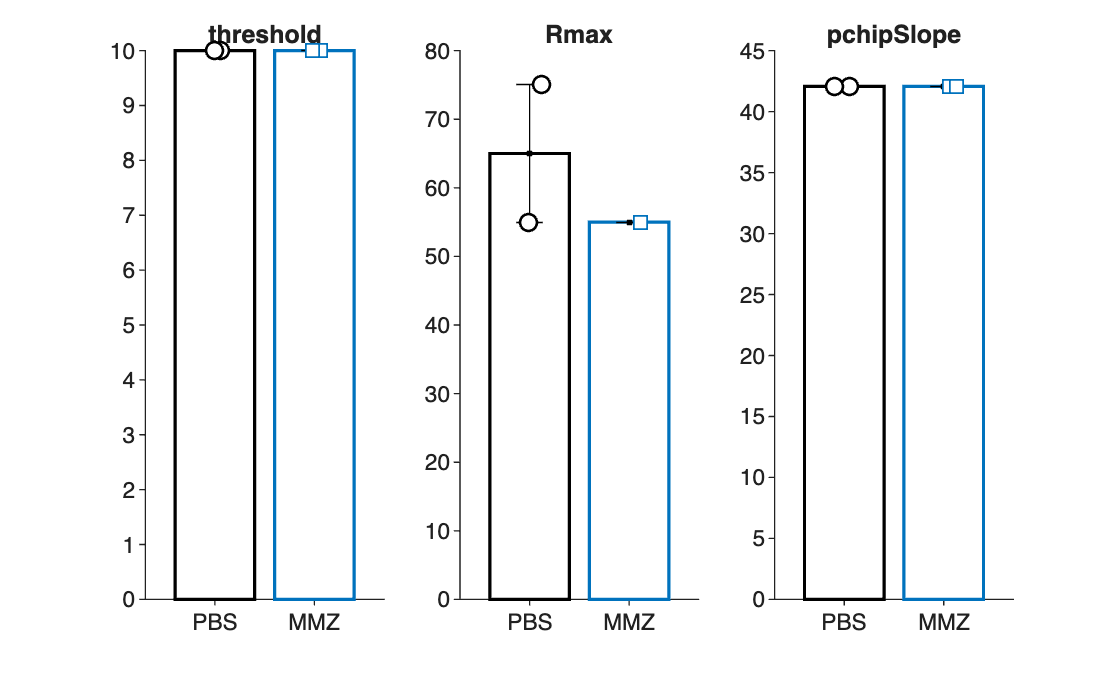

% --- (5) bar charts for threshold / Rmax / pchipSlope ---
figure('Color','w');

% horizontal jitter for datapoint (avoid overlapping of datapoint with similar values)
xJitter = 0.08;
ptSize = 40;


for p = 1:numel(varsParams)
    % 3 subplots, one for each parameter
    subplot(1,3,p); hold on; box off;
    
    % getting datapoint for each parameter of each treatment
    PBS_Parameter_datapoint = T2{T2.treatment=="PBS", varsParams(p)};
    MMZ_Parameter_datapoint = T2{T2.treatment=="MMZ", varsParams(p)};

    % getting parameter mean & SEM for each treatment
    PBS_ParameterMean = stats.PBS.meanPars(p); 
    PBS_ParameterSEM = stats.PBS.semPars(p);

    MMZ_ParameterMean = stats.MMZ.meanPars(p); 
    MMZ_ParameterSEM = stats.MMZ.semPars(p);

    % creating bar plot for each treatment
    b1 = bar(1, PBS_ParameterMean, 'FaceColor','none','EdgeColor','k','LineWidth',1.2);
    b2 = bar(2, MMZ_ParameterMean, 'FaceColor','none','EdgeColor',blue,'LineWidth',1.2);
    
    % adding error bars
    errorbar([1 2], [PBS_ParameterMean MMZ_ParameterMean], [PBS_ParameterSEM MMZ_ParameterSEM], 'k.', 'CapSize',10);

    % adding datapoints
    x1 = 1 + xJitter*randn(numel(PBS_Parameter_datapoint),1);
    scatter(x1, PBS_Parameter_datapoint, ptSize, 'o', ...
            'MarkerEdgeColor','k','MarkerFaceColor','w','LineWidth',1);
    
    x2 = 2 + xJitter*randn(numel(MMZ_Parameter_datapoint),1);
    scatter(x2, MMZ_Parameter_datapoint, ptSize, 's', ...
            'MarkerEdgeColor',blue,'MarkerFaceColor','w','LineWidth',1);

    % axis setting
    xlim([0.3 2.7]); xticks([1 2]); xticklabels({'PBS','MMZ'});
    title(varsParams{p});
    set(gca,'TickDir','out');
end


% === Outputs you can inspect ===
CellCountTbl      % table of treatment vs CellCount

CellCountTbl =      2
     2


stats             % struct with mean/SD/SEM for spikes & parameters

stats = struct with fields:
    MMZ: [1×1 struct]
    PBS: [1×1 struct]



% (Optional) save filtered table
% outFile = fullfile(pwd, 'T_HM_2w_aCSF.xlsx');
% writetable(T_HM_2w_aCSF, outFile, 'FileType','spreadsheet');

% outFile = fullfile(pwd, 'T_HM_2w_aCSF.xlsx');
% writetable(T_HM_2w_aCSF, outFile, 'FileType','spreadsheet'); 


% % --- Column-wise means per treatment (MMZ, PBS) ---
% T2 = T_HM_2w_aCSF;
% T2.treatment = string(T2.treatment);   % grouping key
% 
% varsToMean = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000", ...
%               "threshold","Rmax","pchipSlope"];
% 
% % Safe numeric conversion
% for v = varsToMean
%     x = T2.(v);
%     if isnumeric(x)
%         x = double(x);
%     elseif iscell(x)
%         x = cellfun(@(y) str2double(string(y)), x);
%     else
%         x = str2double(string(x));
%     end
%     T2.(v) = reshape(x,[],1);
% end
% 
% % Mean per treatment, omitting NaNs
% om = @(x) mean(x,'omitnan');
% AvgByTreatment = varfun(om, T2, ...
%     'InputVariables', varsToMean, ...
%     'GroupingVariables', 'treatment');
% 
% % ---- Rename headers ----
% % 1) GroupCount -> CellCount
% if ismember('GroupCount', AvgByTreatment.Properties.VariableNames)
%     AvgByTreatment = renamevars(AvgByTreatment,'GroupCount','CellCount');
% end
% 
% % 2) Strip 'Fun_' prefix from output variable names
% vn = AvgByTreatment.Properties.VariableNames;
% funMask = startsWith(vn,'Fun_');
% if any(funMask)
%     AvgByTreatment = renamevars(AvgByTreatment, vn(funMask), erase(vn(funMask),'Fun_'));
% end
% 
% disp(AvgByTreatment)
% % Write to Excel in the current folder
% outFile = fullfile(pwd, 'AvgByTreatment.xlsx');
% writetable(AvgByTreatment, outFile, 'FileType','spreadsheet');
% fprintf('Wrote %s\n', outFile);

disp(stats.MMZ)

    meanSpikes: [NaN NaN NaN 10 17 44 52 55]
      sdSpikes: [NaN NaN NaN 0 0 0 0 0]
     semSpikes: [NaN NaN NaN 0 0 0 0 0]
       nSpikes: [0 0 0 2 2 2 2 2]
      meanPars: [10 55 42.0757]
        sdPars: [0 0 0]
       semPars: [0 0 0]
         nPars: [2 2 2]

